**Problem 1**

A)

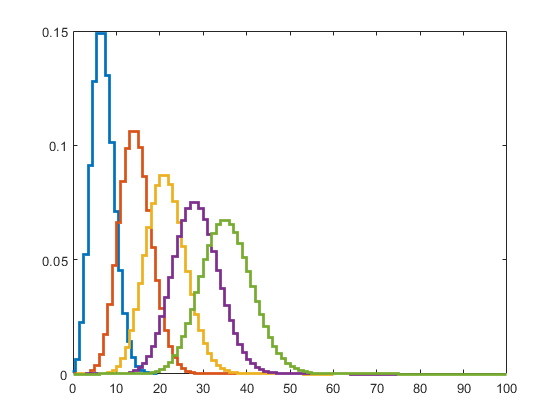

cosmic = makedist("Poisson",'lambda',7); % Create a Poisson distribution for cosmic ray.
x = 0:20;
u = pdf(cosmic,x);
v = u;
stairs(x-0.5,u,"LineWidth",2)
xlim([0,100])
hold on
for i = 1:4
    dayx = conv(u,v);
    x = 0:20*(i+1);
    stairs(x,dayx,"LineWidth",2)
    hold on
    u = dayx;
end
hold off

B)

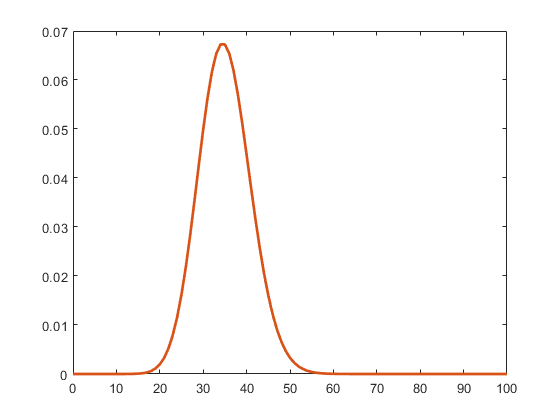

poissontest = makedist("Poisson", 'lambda',7*5);
ytest = pdf(poissontest,x);
plot(x,u,x,ytest,"LineWidth",2)

sum(ytest-u)

ans = 7.2475e-05

Because the sum of the difference between the Poisson distribution after 5 days and the test Poisson distribution with 7 * 5 as the mean value is so small with e-05, they are basically the same. Therefore the summed probability distribution is still a Poisson distribution.

C)

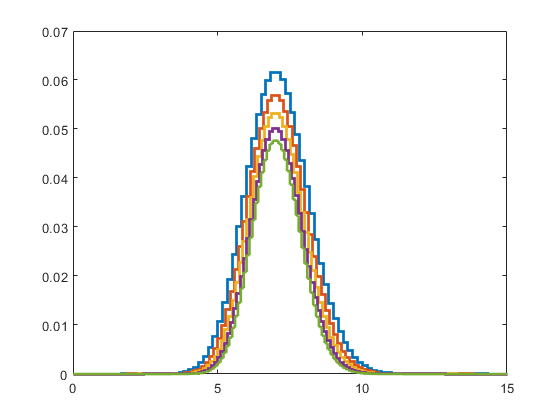

for i = 5:9
    dayx = conv(u,v);
    x = 0:20*(i+1);
    stairs(x/(i+1),dayx,"LineWidth",2)
    xlim([0,15])
    hold on
    u = dayx;
end
hold off

It becomes much more like a Gaussian Distribution as the number of days becomes larger. In part B, the Poisson Distribuion after 5 days in almost a Gaussian Distribution if we plot it with lines but not stairs. As we averaged it, we got more steps between integers and it just basically becoming a Gaussian Distribution. Also, the central limit theorem stated that when distributions are added, their sum tends towards a Gaussian Distribution.

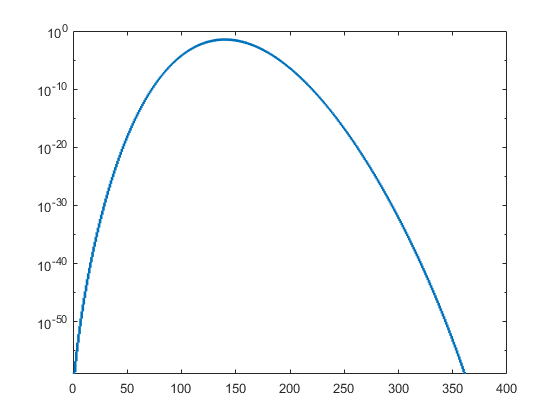

for i = 10:19
    dayx = conv(u,v);
    x = 0:20*(i+1);
    u = dayx;
end
stairs(x,dayx,"LineWidth",2)
ylim([10e-60,1])
set(gca,'YScale','log')

cosmic20 = makedist("Poisson",'lambda',7*20);
gamma = 10*20;
p = cdf(cosmic20,gamma);
sigma = norminv(p)

sigma = 4.8120

**Problem 2**

A)

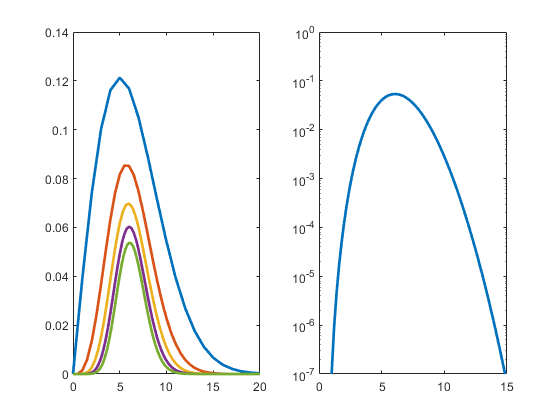

rayl = makedist("Rayleigh",'b',5);
x = 0:20;
u = pdf(rayl,x);
v = u;
subplot(1,2,1)
plot(x,u,"LineWidth",2)
hold on
for i = 1:4
    raylp = conv(u,v);
    x = 0:20*(i+1);
    plot(x/(i+1),raylp,"LineWidth",2)
    hold on
    u = raylp;
end
hold off
subplot(1,2,2)
plot(x/(i+1),raylp,"LineWidth",2)
ylim([10e-8,1])
set(gca,'YScale','log')

B) Yes. after about 2 iteration of averages, the distribution curve is much likely to be an Gaussian Distribution, with a bell-like curve in log view.

**Problem 3**

A)

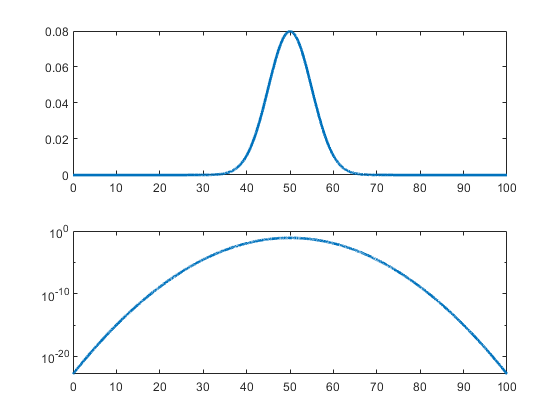

image = makedist("Normal",'mu',50,"sigma",5); % Create a background Gaussian distribution
xpixel = linspace(0,100,10000);
subplot(2,1,2)
plot(xpixel,pdf(image,xpixel),"LineWidth",2)
set(gca,'YScale','log')
subplot(2,1,1)
plot(xpixel,pdf(image,xpixel),"LineWidth",2)

sig = 1-cdf(image,63.24) % Choose 63.24 as the signal and calculate the significance.

sig = 0.0040

sigmaImage = norminv(cdf(image,63.24)) % Calculate 'Sigma' with erfc().

sigmaImage = 2.6480

No, because 'sigma' is not reaching 5.

B) What is the background probability distribution when multiply the pdf in part 1 by 10k times?

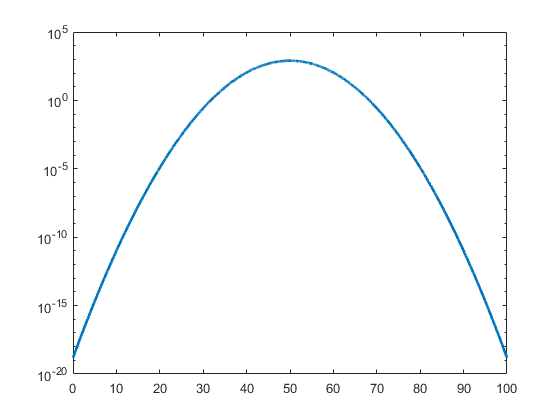

numpixel = 1e4;
ypixel10k = pdf(image,xpixel)*numpixel;
subplot(1,1,1)
plot(xpixel,ypixel10k,"LineWidth",2)
set(gca,'YScale','log')

C)

sig10k = sig*numpixel

sig10k = 40.4848

sigma10k = norminv(sig10k)

sigma10k = NaN

**Problem 4**

A)

prob5sigma = 1/3.5e6;
sig5sigma = icdf(image,1-prob5sigma)

sig5sigma = 75.0032

B)

sig5sigma10k = icdf(image,1-prob5sigma/numpixel)

sig5sigma10k = 82.7551

C)

brighter = (sig5sigma10k-sig5sigma)/sig5sigma

brighter = 0.1034

The signal has to be 10% brighter than the original signal if we have a trails factor of 10k. The sensitivity penalty due to a trails factor is so low because the x range of the distribution is not change after the trails factor applied to the probability distribution, therefore, the mean value of the distribution is not changed.

D)

large = icdf(image,1-prob5sigma/(numpixel*10e4))

large = 90.3829

brighterlarge = (large-sig5sigma)/sig5sigma

brighterlarge = 0.2051

The larger the trials factor, the larger that the threshold will be. From above, we can guess that the treshold will be 10% larger when the trails factor multiplied by 10k every time.

Extra Credit: I think that for different distribution shape, the sensitivity penalty of many trails will still be low because trails will not affect the x range of the probability distribution function, and the mean value of it will still be the same since almost every pdf has a parameter of mean value.